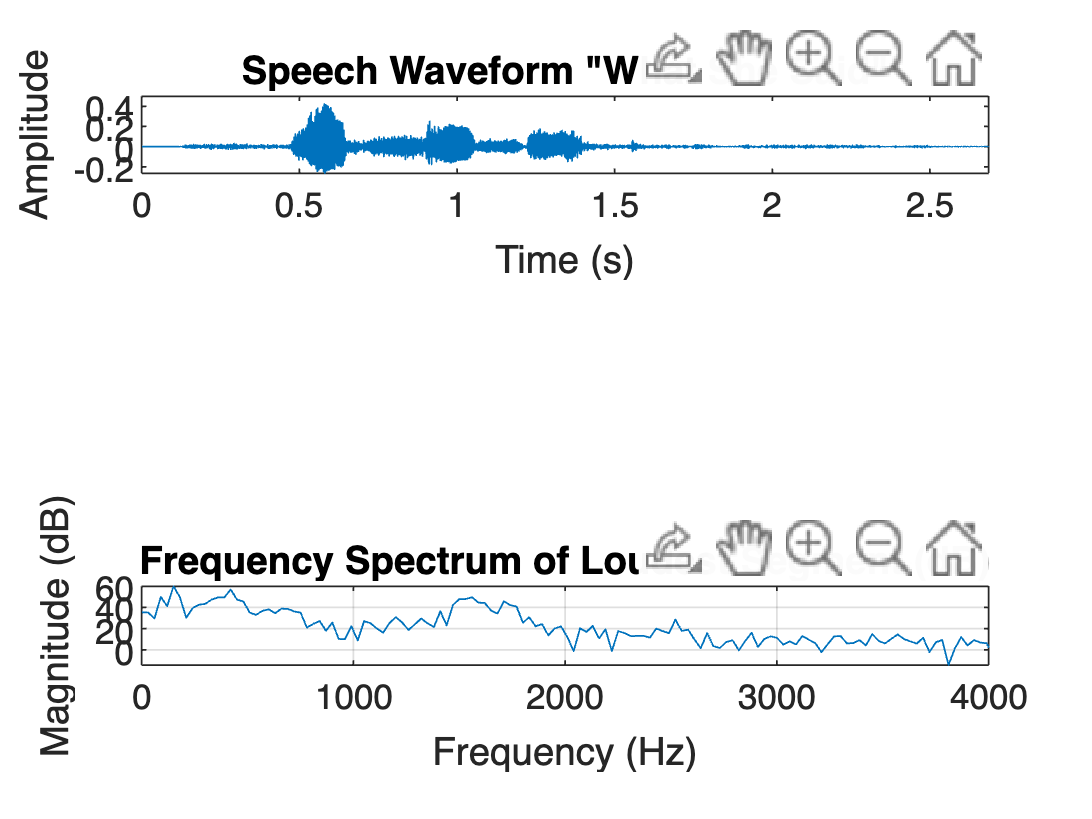

[audio, fs] = audioread('whatshesaid.m4a');

if size(audio, 2) > 1
    audio = audio(:, 1); % Use the left channel only
end

t = (0:length(audio)-1) / fs;

figure;
subplot(3,1,1);
plot(t, audio);
title('Speech Waveform "What She Said"');
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 max(t)]);

segment = audio(best_start:(best_start + segment_length - 1));

f = (0:round(length(segment)/2)-1) * fs / length(segment);
Y = abs(fft(segment) / length(segment));
Y = Y(1:length(f)); 
Y = Y / max(Y); 
Y = Y * 1000;   
subplot(3,1,3);
plot(f, 20 * log10(Y));
title('Frequency Spectrum of Loudest Segment (dB)');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
xlim([0 4000]);
grid on;

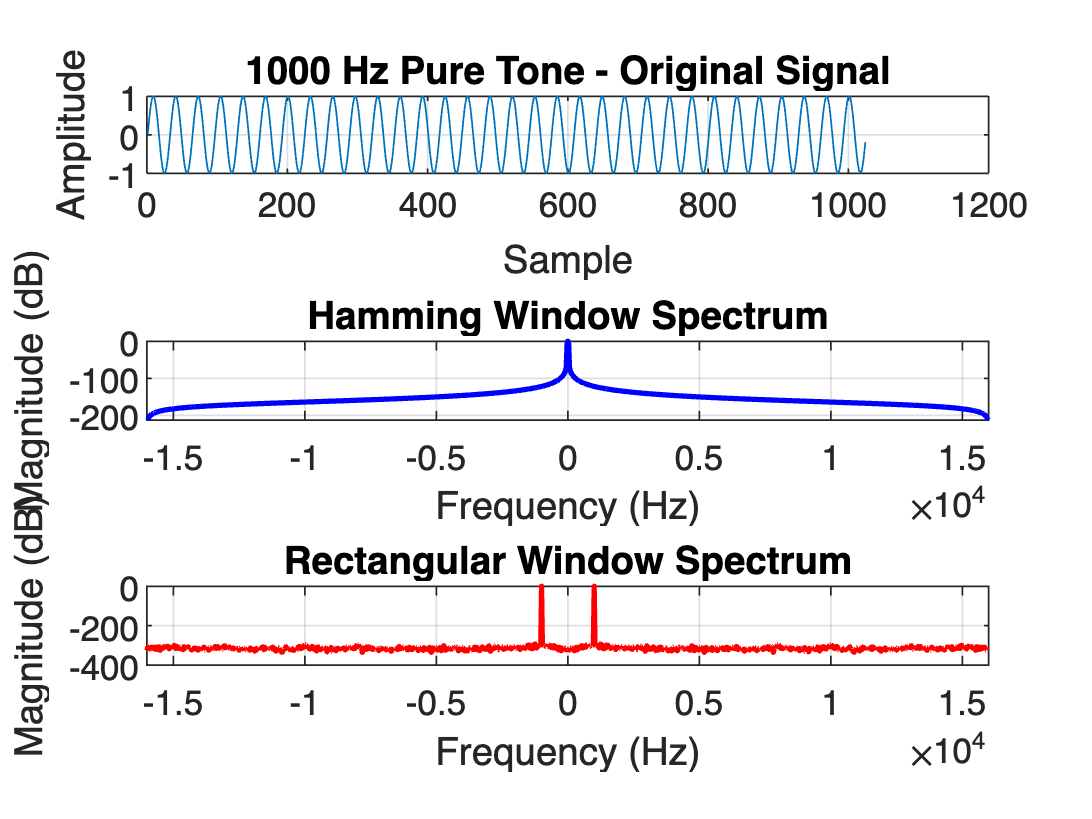

fs = 32000;                     
t = (0:1/fs:1-1/fs);           
signal = sin(2 * pi * 1000 * t); 

N = 1024;
segment = signal(1:N);          

hamming_window = hamming(N) .* segment;
rectangular_window = segment;  

f = (-N/2:N/2-1) * (fs / N);    

hamming_spectrum = abs(fftshift(fft(hamming_window, N)));
rectangular_spectrum = abs(fftshift(fft(rectangular_window, N)));

hamming_spectrum_db = 20 * log10(hamming_spectrum / max(hamming_spectrum));
rectangular_spectrum_db = 20 * log10(rectangular_spectrum / max(rectangular_spectrum));

figure;
subplot(3,1,1);
plot(segment);
title('1000 Hz Pure Tone - Original Signal');
xlabel('Sample');
ylabel('Amplitude');
grid on;

subplot(3,1,2);
plot(f, hamming_spectrum_db, 'b', 'LineWidth', 1.5);
title('Hamming Window Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
xlim([-fs/2 fs/2]);
grid on;

subplot(3,1,3);
plot(f, rectangular_spectrum_db, 'r', 'LineWidth', 1.5);
title('Rectangular Window Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
xlim([-fs/2 fs/2]);
grid on;


[audio, fs] = audioread('we were away a year ago_lrr.wav');
audio = audio(:, 1);

segment = audio(1:round(0.5 * fs));

t = (0:length(segment)-1) / fs;
high_freq_noise = 0.5 * (sin(2 * pi * 6000 * t) + sin(2 * pi * 8000 * t));

noisy_signal = segment + high_freq_noise;

bp_filter = designfilt('bandpassiir','FilterOrder',8, ...
                       'HalfPowerFrequency1',300,'HalfPowerFrequency2',3400, ...
                       'SampleRate',fs);

filtered_signal = filter(bp_filter, noisy_signal);

figure;
subplot(3,1,1);
plot(t, noisy_signal);
title('Noisy Speech Signal (Speech + High-Frequency Noise)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(3,1,2);
plot(t, filtered_signal);
title('Bandpass Filtered Signal (300 - 3400 Hz)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

f = (-fs/2:fs/length(noisy_signal):fs/2 - fs/length(noisy_signal));
original_spectrum = abs(fftshift(fft(noisy_signal)));
filtered_spectrum = abs(fftshift(fft(filtered_signal)));

subplot(3,1,3);
plot(f, original_spectrum, 'r', 'LineWidth', 1.5, 'DisplayName', 'Noisy Signal');
hold on;
plot(f, filtered_spectrum, 'b', 'LineWidth', 2.5, 'DisplayName', 'Filtered Signal');
xlim([-5000 5000]);
title('Frequency Domain - Before and After Filtering');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend('Noisy Signal', 'Filtered Signal');
grid on;